## Motion Blur

### Aplicación de Motion Blur

PSF = fspecial('motion', 30, 20);
lena = im2double(lena);

figure

### Image blurrying

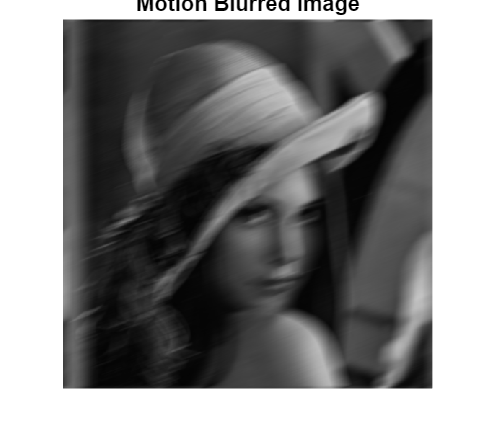

blurred = imfilter(lena, PSF, 'conv', 'circular');
imshow(blurred)
title('Motion Blurred Image')

MSE_blurred = 2*mse(blurred, lena)

MSE_blurred = 0.0114

### Wiener

Deconvoluciona una imagen `I` usando el algoritmo del filtro de Wiener, devolviendo enfocada la imagen borrosa `J`. Necesita de la función de dispersión puntual (PSF) con la que `I` fue convolucionada. El algoritmo es óptimo en un sentido de error cuadrático medio mínimo entre las imágenes estimadas y reales.

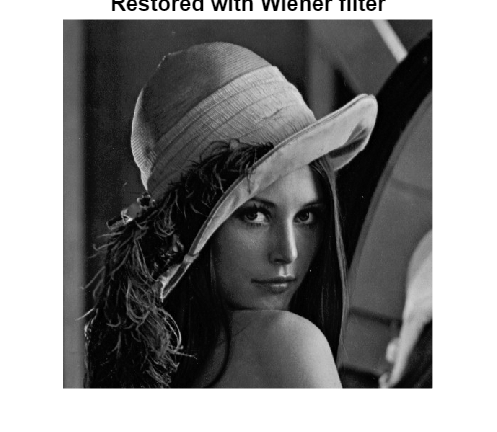

wiener = deconvwnr(blurred, PSF);
imshow(wiener)
title('Restored with Wiener filter')

MSE_wiener = 2*mse(wiener, lena)

MSE_wiener = 2.3319e-06

### Lucy-Richardson

Restaura una imagen `I` que se degradó mediante convolución con una función de dispersión puntual (PSF), `psf`, y posiblemente mediante ruido aditivo. El algoritmo se basa en maximizar la probabilidad de que la imagen resultante `J` sea una instancia de la imagen original `I` según las estadísticas de Poisson.

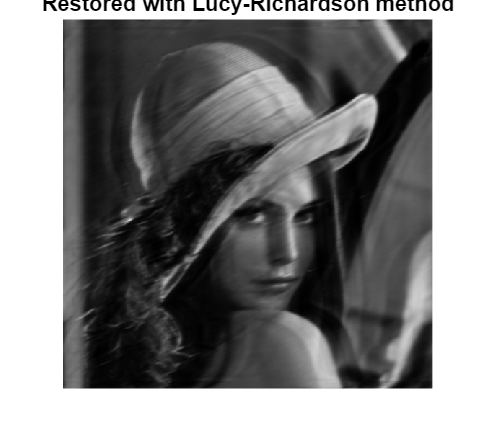

lucy = deconvlucy(blurred, PSF);
imshow(lucy)
title('Restored with Lucy-Richardson method')

MSE_lucy = 2*mse(lucy, lena)

MSE_lucy = 0.0038

Observamos que la restauración con el filtro de Wiener fue mucho más fructifera en terminos del error cuadrático medio asociado